# Pattern Nulling Lab

Sometimes it may be desirable to reduce the antenna pattern in a certain direction. For example, if there is a known emitter in that direction that is interfering with the systems ability to monitor a desired signal.

In this lab, we look at a simple approach for inserting a null into the antenna pattern in a certain direction.

## Setup

First, put the HB100 transmitter as close to boresight as possible.

Run the following to clear the workspace.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

We also load the calibration weights which are applied so that the beam pattern matches our expectations.

load('CalibrationWeights.mat','calibrationweights');

We also load the frequency of the transmitter being used.

load('HB100_Fc.mat','fc_hb100');

### Create Antenna Interactor

The antenna interactor object helps us to interact with the phaser board to steer the beam and collect data. Create this object so that we can control the antenna.

ai = AntennaInteractor(fc_hb100,calibrationweights);

### Create Antenna Model

In order to generate amplitudes and phases to change the antenna pattern behavior, we need to have an approximate model of the antenna array. The Phaser antenna array is made up of two four-element uniform linear arrays (ULA). The antenna element spacing is 1/2 wavelength at a frequency of 10.39875 GHz. We create this antenna model below.

lambda = freq2wavelen(10.39875e9);
spacing = lambda/2;
array = phased.ULA(NumElements=8,ElementSpacing=spacing);
elementLocation = array.getElementPosition();

## Pattern Nulling demonstration

In this lab, we place a null in the antenna pattern and see how the pattern is impacted by collecting the antenna pattern with the given steering and nulling angle.

We use the same data collection approach that was used in the Antenna Pattern Collection Lab. We place the HB100 somewhere and ask you to rotate the Phaser so that the angle of the HB100 changes. We can observe how the pattern nulling impacts the antenna pattern.

Try changing the nulling angle and steering angle to see how the antenna pattern is impacted.

% Set null and steer angle
nullAngle = 0;
steerAngle = 22;

% Initialize the data collection values
azAngles = -90:0.5:90;
nAngles = length(azAngles);
nullPattern = nan(1,nAngles);
noNullPattern = nan(1,nAngles);

% Create a plot for the antenna pattern and for the desired transmitter
% angle
f = tiledlayout(2,1);
patAx = nexttile(f);
azAx = nexttile(f);

% Create a line on the pattern axes to plot the pattern
hold(patAx,"on");
nullPatLine = plot(patAx,azAngles,nullPattern,DisplayName='Pattern With Null');
noNullPatLine = plot(patAx,azAngles,noNullPattern,DisplayName='Pattern Without Null');
xline(patAx,nullAngle,LineStyle="--",Color='r',DisplayName='Null Angle');
xline(patAx,steerAngle,LineStyle="--",Color='g',DisplayName='Steer Angle');
xlim(patAx,[-90 90]);
title(patAx,'Array Pattern');
xlabel(patAx,'Azimuth Collection');
ylabel(patAx,'Magnitude (dB)');
legend(patAx,Location="southeast");

% Create a line on the azimuth axes to plot the desired tx location
azLine = xline(azAx,azAngles(1),LineStyle='--',LineWidth=2);
xlim(azAx,[-90 90]);
title(azAx,'Desired Transmit Location');
xlabel(azAx,'Tranzmitter Azimuth');
azAx.YAxis.Visible = false;

We capture the collected magnitude with and without nulling applied for multiple time steps and plot the difference. In order to insert a null, we substract the null weights from the steering weights.

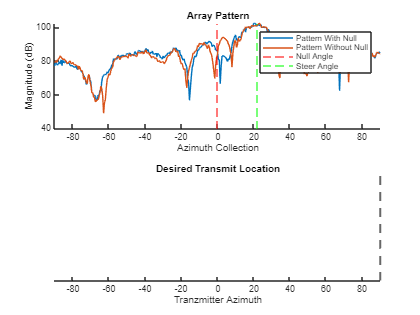

for i = 1:nAngles
     % Set current angle
    azLine.Value = azAngles(i);
    drawnow;

    % Get the steering vector that directs the beam in the desired
    % direction
    steerweights = steervec(elementLocation/freq2wavelen(fc_hb100),[steerAngle;0]);

    % Get the steering vector for the null direction
    nullweights = steervec(elementLocation/freq2wavelen(fc_hb100),[nullAngle;0]);

    % Calculate the null steering weights
    rn = sum(diag(nullweights'*steerweights))/sum(diag((nullweights'*nullweights)));
    nullsteer = steerweights-nullweights.*rn;

    % Get the signal magnitude with nulling
    nullsteer = analogWeightsCalAdjustment([nullsteer(1:4) nullsteer(5:8)],calibrationweights.AnalogWeights);
    data = ai.steerAnalog(nullsteer);
    digitalsteer = digitalWeightsCalAdjustment([1;1],calibrationweights.DigitalWeights);
    data = data * conj(digitalsteer);
    nullPattern(i) = mag2db(helperGetAmplitude(data));

    % Get the signal magnitude without nulling
    steerweights = analogWeightsCalAdjustment([steerweights(1:4) steerweights(5:8)],calibrationweights.AnalogWeights);
    data = ai.steerAnalog(steerweights);
    digitalsteer = digitalWeightsCalAdjustment([1;1],calibrationweights.DigitalWeights);
    data = data * conj(digitalsteer);
    noNullPattern(i) = mag2db(helperGetAmplitude(data));

    % Plot the updated pattern with and without nulling
    nullPatLine.YData = nullPattern;
    noNullPatLine.YData = noNullPattern;
    drawnow;
end

% Perform cleanup
cleanup(ai);